% Load variables
exp2 = load("C:\Users\amahesh\Downloads\exp2.mat");
Ch23 = exp2.Ch2;
Imeasure3 = exp2.Imeasure;
Isource3 = exp2.Isource;
Vout3 = exp2.Vout;
clear exp2;

% Display results
Ch23,Imeasure3,Isource3,Vout3

Ch23 = 5

Imeasure3 =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Isource3 = 1.0e-03 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Vout3 =     0.3266    0.3272    0.3276    0.3279    0.3282    0.3285    0.3288    0.3291    0.3295    0.3298    0.3301    0.3305    0.3308    0.3312    0.3315    0.3319    0.3322    0.3326    0.3330    0.3333    0.3337    0.3340    0.3344    0.3347    0.3354    0.3355    0.3358    0.3362    0.3365    0.3369    0.3371    0.3369    0.3385    0.3400    0.3387    0.3386    0.3391    0.3397    0.3401    0.3405    0.3410    0.3414    0.3418    0.3422    0.3426    0.3430    0.3434    0.3438    0.3442    0.3446



loglog(Isource3, Imeasure3,".", "DisplayName","Experimental Plot")
hold on
title("Measured Current against Source Current")
xlabel("Source Current(A)")
ylabel("Measured Current(A)")
slope = Imeasure3'\Isource3'

slope = 0.9469

loglog(Isource3, Isource3,"-", "DisplayName","Theoretical Plot: slope = 1")
error = abs(Imeasure3 - Isource3)./Isource3

error =     0.1220    0.1408    0.1342    0.1370    0.1305    0.1297    0.1327    0.1299    0.1374    0.1325    0.1314    0.1364    0.1324    0.1347    0.1298    0.1338    0.1341    0.1401    0.1325    0.1373    0.1339    0.1358    0.1364    0.1302    0.1324    0.1411    0.1349    0.1352    0.1335    0.1363    0.1291    0.1176    0.1407    0.1590    0.1280    0.1221    0.1282    0.1325    0.1294    0.1346    0.1343    0.1302    0.1344    0.1335    0.1359    0.1349    0.1355    0.1333    0.1337    0.1350


percent_error = 100*sum(error)/1000

percent_error = 11.1219

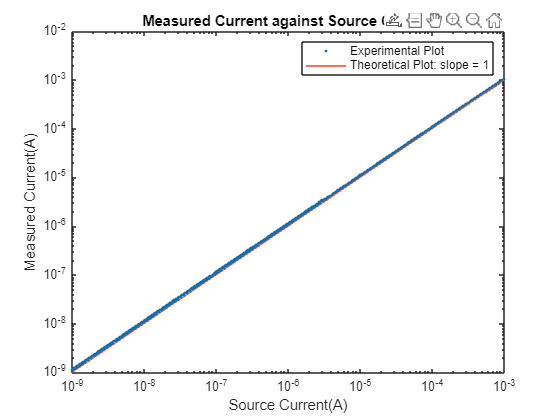

legend()
hold off